# Setup Workspace

clc; clear all; close all;

# System ID

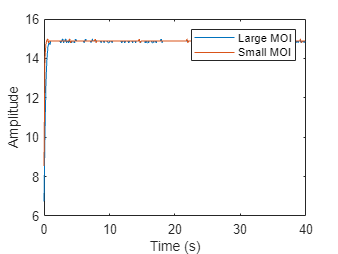

% Motor Counts
Counts_BW = importdata('Copy_of_Motor_bw_counts.txt'); % [counts/ms]
Counts_BW = (2*pi*Counts_BW/(211)); % [rad/ms]

Counts_SW = importdata('Motor_sw_counts.txt'); % [counts/ms]
Counts_SW = (2*pi*Counts_SW/(211)); % [rad/ms]

t = linspace(0,40,length(Counts_BW));
t2 = linspace(0,40,length(Counts_SW));

N=0;

Speed_BW=length(t);

for N = 1:length(Counts_BW)-1

    Speed_BW(N) = (Counts_BW(N+1) - Counts_BW(N))/((0.1)); % 0.1s intervals

end

N=0;

Speed_SW=length(t2);

for N = 1:length(Counts_SW)-1

    Speed_SW(N) = (Counts_SW(N+1) - Counts_SW(N))/(0.1); % 0.1s intervals


end

% Responses
figure;
plot(t(1:end-1), Speed_BW/3) % dividing by V_in
hold on
plot(t2(1:end-1), Speed_SW/3)
legend('Large MOI', 'Small MOI')
xlabel('Time (s)')
ylabel('Amplitude')

%xlim([0 2]);


# fitting

% Inverse L of second order TF
K_hat = 44.66/3; % divide by 3v 
sigma_SMOI = 14;
sigma_LMOI = 7;
y = K_hat*(1 - exp(-sigma_LMOI*t)) % Large MOI

y =          0    9.6910   13.0733   14.2538   14.6658   14.8096   14.8598   14.8773   14.8834   14.8855   14.8863   14.8865   14.8866   14.8866   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867


y2 = K_hat*(1 - exp(-sigma_SMOI*t2)) % Small MOI

y2 =          0   12.7856   14.5901   14.8448   14.8808   14.8858   14.8865   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867   14.8867


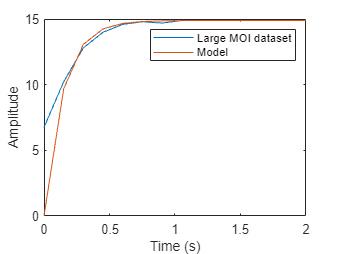


figure;
plot(t(1:end-1), Speed_BW/3)
hold on
plot(t , y)
legend('Large MOI dataset', 'Model')
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0 2]);

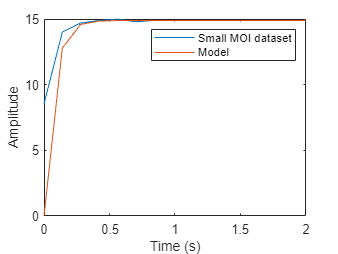


figure;
plot(t2(1:end-1), Speed_SW/3)
hold on
plot(t2, y2)
legend('Small MOI dataset', 'Model')
xlabel('Time (s)')
ylabel('Amplitude')
xlim([0 2]);


%modelfun = @(b,t) b(1)*(1-exp(-b(2)*t));
%beta0 = [10000, 0.0001];

%beta = nlinfit(t,Counts_BW',modelfun,beta0)

%y_fit = beta(1)*(1-exp(-beta(2)*t));

%figure;
%plot(t, y_fit)

# Plant 

s = tf('s');

k = K_hat;

G_omega = k*(sigma_SMOI/((s+sigma_SMOI)))

G_omega =
 
  208.4
  ------
  s + 14
 
Continuous-time transfer function.
Model Properties


G_theta_SMOI = k*(sigma_SMOI/(s*(s+sigma_SMOI)))

G_theta_SMOI =
 
    208.4
  ----------
  s^2 + 14 s
 
Continuous-time transfer function.
Model Properties


G_theta_LMOI = k*(sigma_LMOI/(s*(s+sigma_LMOI)))

G_theta_LMOI =
 
    104.2
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.
Model Properties


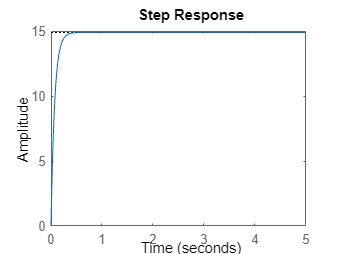



figure;
step(G_omega, 5)

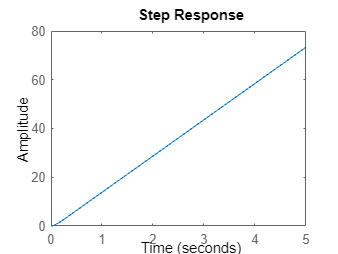

figure;
step(G_theta_SMOI, 5)

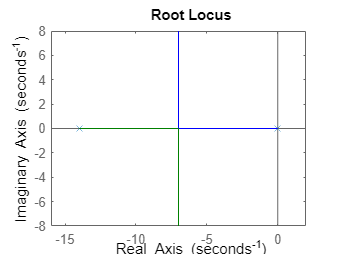

figure;
rlocus(G_theta_SMOI)


G_theta_CL_SMOI = feedback(G_theta_SMOI,1)

G_theta_CL_SMOI =
 
        208.4
  ------------------
  s^2 + 14 s + 208.4
 
Continuous-time transfer function.
Model Properties


G_theta_CL_LMOI = feedback(G_theta_LMOI,1)

G_theta_CL_LMOI =
 
        104.2
  -----------------
  s^2 + 7 s + 104.2
 
Continuous-time transfer function.
Model Properties


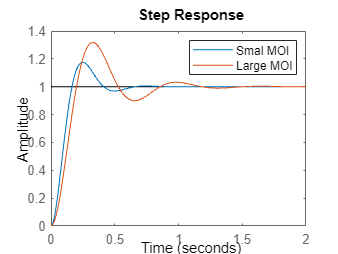


figure;
step(G_theta_CL_SMOI)
hold on
step(G_theta_CL_LMOI)
legend('Smal MOI', 'Large MOI')

# Controller

kP = 0.1;
kI = 0.01;

%tau  = 1/((kP/kD)*100)

C_PI = (kP + kI/s)

C_PI =
 
  0.1 s + 0.01
  ------------
       s
 
Continuous-time transfer function.
Model Properties


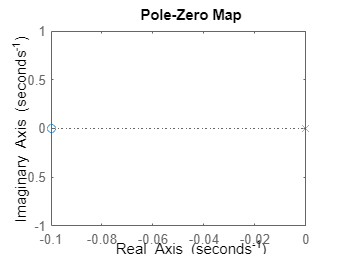


figure;
pzmap(C_PI)

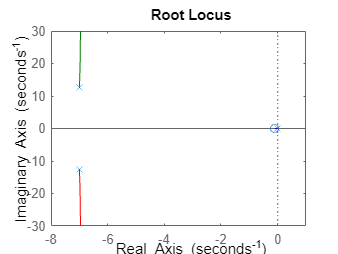


% Plot Response to Step Reference
R = 100; % target:100 rad/s
[y_pd_SMOI, t4] = step(R * feedback(C_PI * G_theta_SMOI, 1), 10);
[y_pd_LMOI, t5] = step(R * feedback(C_PI * G_theta_LMOI, 1), 10);

figure;
rlocus(C_PI*G_theta_CL_SMOI)

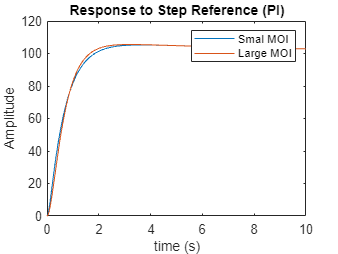


figure;
plot(t4, y_pd_SMOI)
hold on
plot(t5, y_pd_LMOI)
title('Response to Step Reference (PI)');
xlabel('time (s)')
ylabel('Amplitude')
legend('Smal MOI', 'Large MOI')

%xlim([0 2])

# Digitial Controller + Plant

Ts = 0.01; % TC set to 1000us -> 1ms in Arduino IDE
C_PI_z = c2d(C_PI, Ts, 'Tustin')

C_PI_z =
 
  0.1001 z - 0.09995
  ------------------
        z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties



G_theta_z_SMOI = c2d(G_theta_SMOI, Ts)

G_theta_z_SMOI =
 
  0.009951 z + 0.009497
  ----------------------
  z^2 - 1.869 z + 0.8694
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


G_theta_z_LMOI = c2d(G_theta_LMOI, Ts)

G_theta_z_LMOI =
 
  0.005091 z + 0.004973
  ----------------------
  z^2 - 1.932 z + 0.9324
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


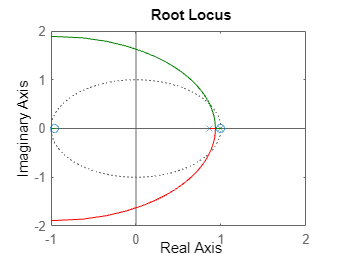


figure;
rlocus(C_PI_z*G_theta_z_SMOI)
xlim([-1 2])

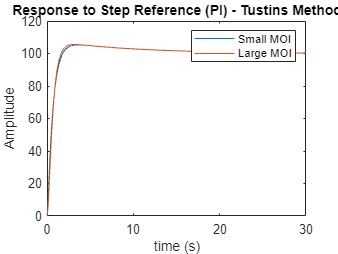



[y_pi_z_SMOI, t_z] = step(R * feedback(C_PI_z * G_theta_z_SMOI, 1), 30);
[y_pi_z_LMOI, t_z2] = step(R * feedback(C_PI_z * G_theta_z_LMOI, 1), 30);

figure;
plot(t_z, y_pi_z_SMOI)
title('Response to Step Reference (PI) - Tustins Method');
xlabel('time (s)')
ylabel('Amplitude')
hold on 
plot(t_z2, y_pi_z_LMOI)
legend('Small MOI', 'Large MOI')

# Motor Response with Controller

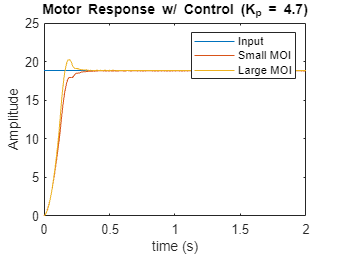

% Big wheel 
MRes_BW_kp5 = importdata('BWMOI_Kp5.txt');
t_kp5 = linspace(0,3,length(MRes_BW_kp5));

MRes_BW_kp0048 = importdata('BMOI_kp0048.txt');
t_kp5_4 = linspace(0,10,length(MRes_BW_kp0048));

% Small wheel
MRes_SW_kp5 = importdata('SWMOI_Kp5.txt');
t_kp5_2 = linspace(0,10,length(MRes_SW_kp5));

MRes_SW_kp0048 = importdata('SMOI_kp0048.txt');
t_kp5_3 = linspace(0,10,length(MRes_SW_kp0048));

Input_r = 6*pi*ones(length(t_kp5_3));


figure;
plot(t_kp5, 6*pi*ones(length(t_kp5))) % ref
hold on
%figure;
plot(t_kp5_2, MRes_SW_kp5)
title('Motor Response w/ Control (K_{p} = 4.7)');
xlabel('time (s)')
ylabel('Amplitude')
hold on
plot(t_kp5, MRes_BW_kp5)
xlim([0 2])
legend('Input', 'Small MOI', 'Large MOI')

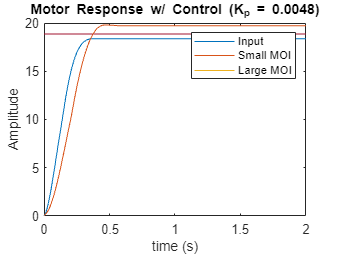


figure;
plot(t_kp5_3, Input_r)
hold on
plot(t_kp5_3, MRes_SW_kp0048)
title('Motor Response w/ Control (K_{p} = 0.0048)');
xlabel('time (s)')
ylabel('Amplitude')
hold on
plot(t_kp5_4, MRes_BW_kp0048)
xlim([0 2])
legend('Input', 'Small MOI', 'Large MOI')